The Build-Up of Aerosols Carrying the SARS-CoV-2 Coronavirus paper


$$\frac{d}{d t} C=E / V_{I}-\lambda C$$


$\lambda$ the decay coefficient of the concentration

$E$ the exhalation rate

$V_I$the volume of the pyramid

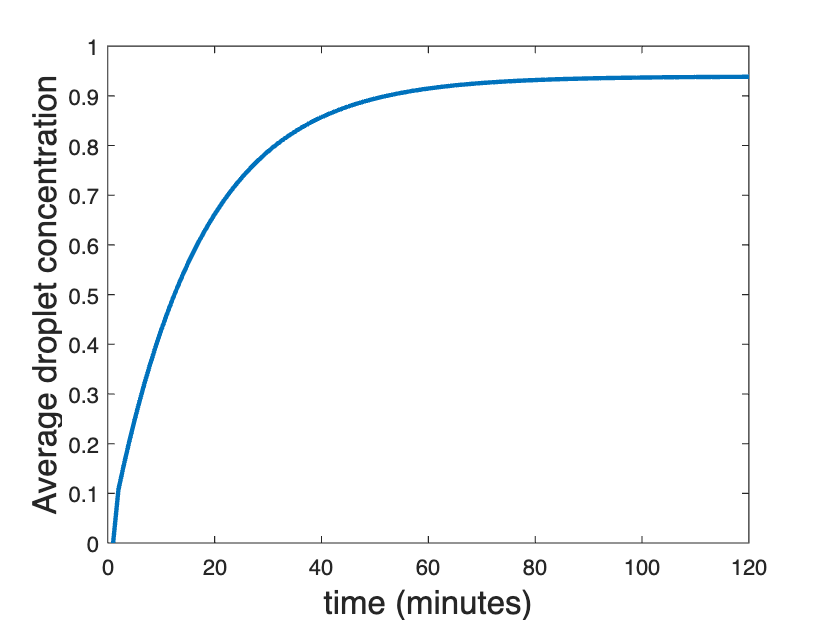

% Copyright 2021 Bjorn Birnir
clear all
figure(1), clf
figure(2), clf
figure(3), clf
%figure(4), clf
k0=0.0031;   %21 RH relative humidity
k5=0.0078;   %35 RH
ka=0.016;    %51 RH
kb=0.024;    %65 RH
kc=0.028;     %81 RH
k6=0.01; %0.6 ACH
k1=0.016; %1 ACH
k2=0.025; %1.5 ACH
k3=0.1; %6ACH this is with the standard 6ACH
kj=3.19/60;% This is the ACH=3.20 in the office. It assumes
% that a vindow is open.
% Exhalation rate per minute E=1.584 m^2/min.
V=27.67;% Volume of the room in meters cubed.
C(1)=1.584/(V);
p(1)=0.6*(1-exp(-C(1))); %We are assuming that most people are
% vaccinated 0.3 but the strain is virulent (omicron) x 2 =0.6.
%pb(1)=320*p(1)*(1-p(1))^(319);
%pb(1)=(factorial(4)/(factorial(2)*factorial(2)))*p(1)^2*(1-p(1))^2;% 4 people and 2 get infected
pb(1)=(factorial(3)/(factorial(2)*factorial(1)))*p(1)^1*(1-p(1))^2;
k=k5+kj;
%C(1)=C(1)/k
for j=2:1:120
C(j)=(C(1)/k)*(1-exp(-k*j));
p(j)=0.6*(1-exp(-C(j)/k+C(1)*j));
%pb(j)=(factorial(4)/(factorial(2)*factorial(2)))*p(j)^2*(1-p(j))^2;
pb(j)=(factorial(3)/(factorial(2)*factorial(1)))*p(j)^1*(1-p(j))^2; %This is the probability that 2 people come into
%office and one gets infected (so there are 3 people there)
end
C(1)=0;
p(1)=0;
pb(1)=0;
%
figure(1), clf
plot(C,'LineWidth',2);hold on
ylabel('Average droplet concentration','FontSize',15), xlabel('time (minutes)','FontSize',15)

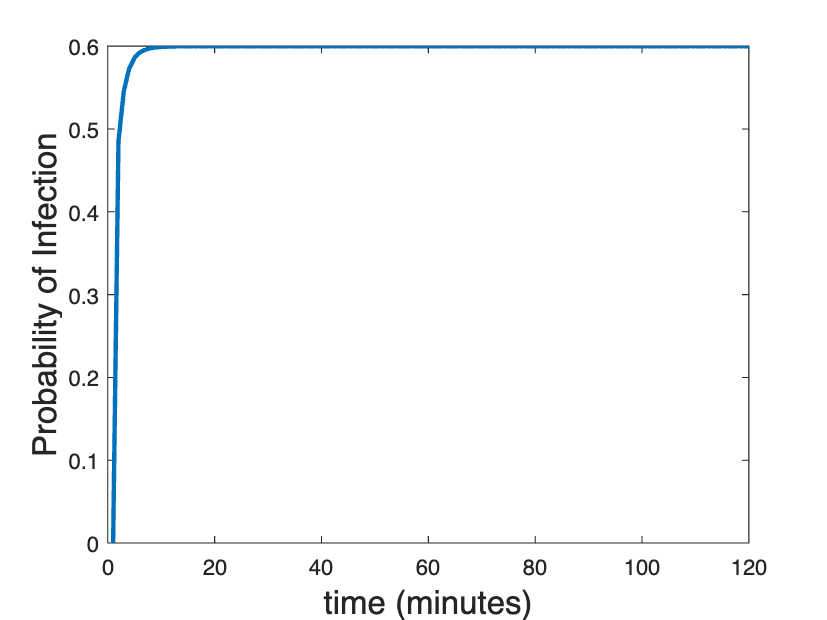

figure(2), clf
plot(p,'LineWidth',2);hold on
ylabel('Probability of Infection','FontSize',15), xlabel('time (minutes)','FontSize',15)

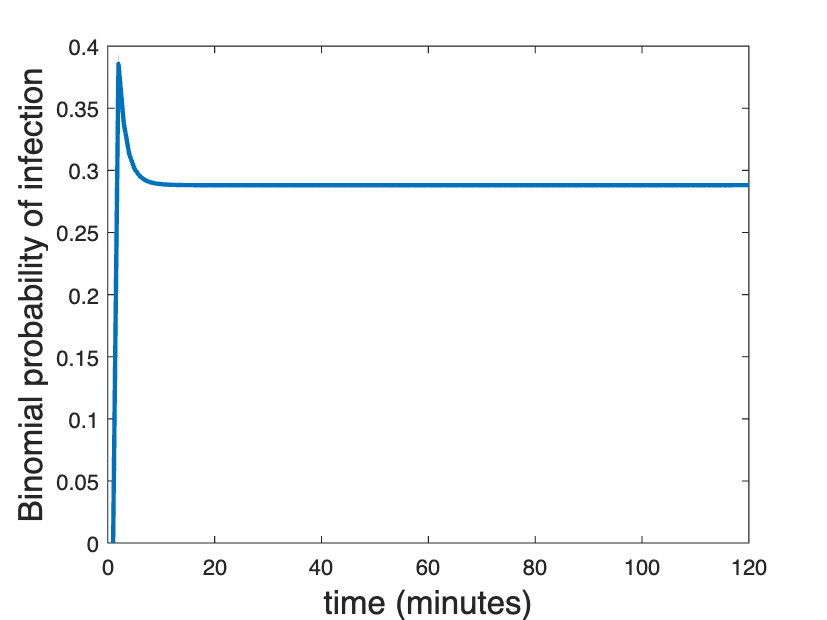

figure(3), clf
plot(pb,'LineWidth',2);hold on
ylabel('Binomial probability of infection','FontSize',15), xlabel('time (minutes)','FontSize',15)

Experimental investigation of indoor aerosol dispersion and accumulation in the context of COVID-19 Paper,

Room volumne is (not $V_I$):


$$V = 7.8 \times 5.7 \times 2.7 \mathrm{~m} \approx 120 m^3$$


The differential equation is


$$\frac{d c}{d t}=R-\lambda c$$


The solution to above is 


$$c^{*}(t)=\frac{R^{*}}{\lambda^{*}}\left(1-e^{-\lambda^{*} t}\right)$$


The simulated result is 


$$\begin{array}{ccc}
R^{*}(\% \mathrm{~h}) & \lambda^{*}\left(\mathrm{~h}^{-1}\right) & c_{\mathrm{sat}}^{*}=R^{*} / \lambda^{*}(\%) \\
\hline 0.53 \pm 0.11 & 0.46 \pm 0.11 & 1.13 \pm 0.057
\end{array}$$


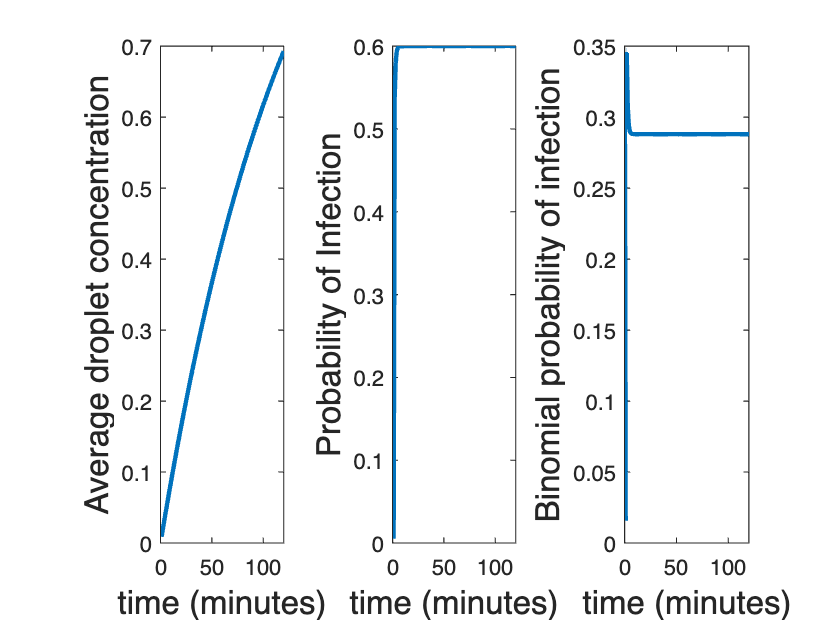

C(1)= 0.53/60;
k = 0.46/60;
p(1)=0.6*(1-exp(-C(1))); %We are assuming that most people are
% vaccinated 0.3 but the strain is virulent (omicron) x 2 =0.6.
%pb(1)=320*p(1)*(1-p(1))^(319);
%pb(1)=(factorial(4)/(factorial(2)*factorial(2)))*p(1)^2*(1-p(1))^2;% 4 people and 2 get infected
pb(1)=(factorial(3)/(factorial(2)*factorial(1)))*p(1)^1*(1-p(1))^2;
%C(1)=C(1)/k
for j=2:1:120
C(j)=(C(1)/k)*(1-exp(-k*j));
p(j)=0.6*(1-exp(-C(j)/k+C(1)*j));
%pb(j)=(factorial(4)/(factorial(2)*factorial(2)))*p(j)^2*(1-p(j))^2;
pb(j)=(factorial(3)/(factorial(2)*factorial(1)))*p(j)^1*(1-p(j))^2; %This is the probability that 2 people come into
%office and one gets infected (so there are 3 people there)
end

%
subplot(1,3,1)
plot(C,'LineWidth',2);hold on
ylabel('Average droplet concentration','FontSize',15), xlabel('time (minutes)','FontSize',15)
subplot(1,3,2)
plot(p,'LineWidth',2);hold on
ylabel('Probability of Infection','FontSize',15), xlabel('time (minutes)','FontSize',15)
subplot(1,3,3)
plot(pb,'LineWidth',2);hold on
ylabel('Binomial probability of infection','FontSize',15), xlabel('time (minutes)','FontSize',15)


$$\lambda=k_{v}+k_{s}+k_{d}$$


Bus Station:


$$V_{bus} = 77.72 m^3$$



$$(E/V_I)_{bus} = \frac{2.45}{3}$$



$$\lambda_{bus} = 0.05$$


Chinese Restaurant:


$$k_v  = 0 $$



$$k_s = 0$$



$$k_d =0.0031$$



$$\lambda_{res}=k_{v}+k_{s}+k_{d} = 0.0031$$



$$(E/V_I)_{res} = 0.0086$$


Korean Call Center: